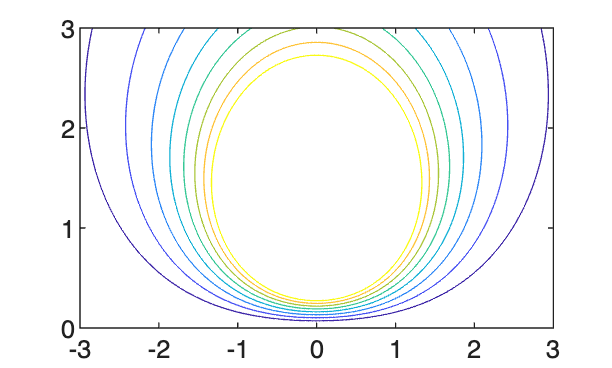

clc
clear all
e=1.602e-19;
h=1.2;
q1=2;
q2=-q1;
ep=8.85*1e-12;
k=9.0e9;
a=3;
[x,y]=meshgrid(-a:0.01:a,0:0.01:a);
r1=sqrt(x.^2+(y-h).^2);
r2=sqrt(x.^2+(y+h).^2);
U=k*e*(q1./r1+q2./r2);
u0=k*e/5;
v=linspace(1,4,8)*u0;
contour(x,y,U,v,'-');

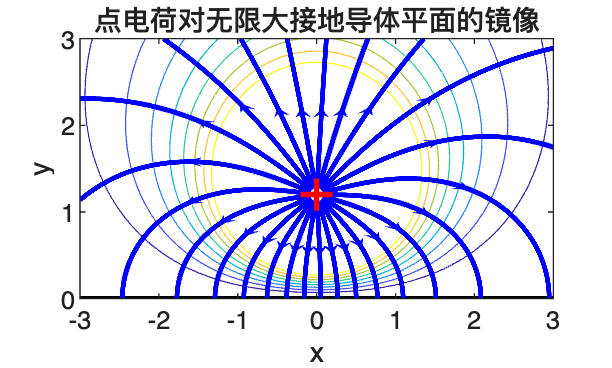


[Ex,Ey]=gradient(-U);
hold on
plot([-a,a],[0,0],'k','linewidth',2);
title('点电荷对无限大接地导体平面的镜像');
xlabel('x');
ylabel('y');
Ne=26;
t=linspace(0,2*pi,Ne);
rd=0.08;
start_x1=rd*cos(t);
start_y1=h+rd*sin(t);
for i=1:Ne
    he=streamline(x,y,Ex,Ey,start_x1(i),start_y1(i));
    arrowPlot(he.XData,he.YData,'number',1,'color','b','LineWidth',2);
    hold on;
end
plot(0,h,'r+','MarkerSize',12,'LineWidth',2);
hold off